Nonstationary signal analysis

A = [3 2 1];
f = [ 10 20 30];
phi = 2 * pi * rand(1,3) - pi ; % ensure it is between minus pi and pi
ts = 0;
te = 9;
fs = 100;
Ts = 1/fs;
SNR = 40;
c = 1

c = 1

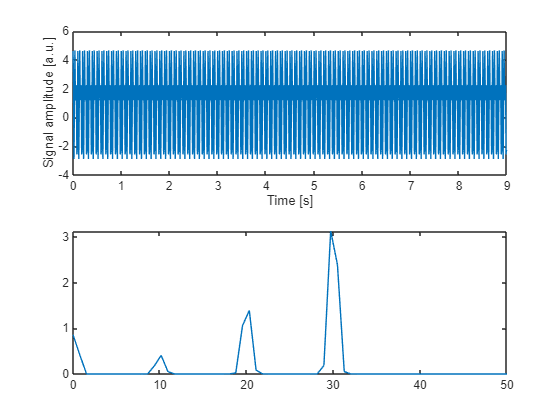

[s,sn,t] = generate_cos_sig_multi(c,A,f,phi,ts,te,Ts,SNR);

figure
subplot(211)
plot(t,s)
xlabel('Time [s]')
ylabel('Signal amplitude [a.u.]')
% frequency domain
NFFT = 128;
NOVERLAP = NFFT/2;
WINDOW = hanning(NFFT);
[Pss, F] = pwelch(s, WINDOW, NOVERLAP, NFFT, fs);
subplot(212)
plot(F, Pss)
hold off;

## Consider a nonstationary signal with the same three frequency components

[s1, sn1 ,t1 ] = generate_cos_sig_multi(c,A(1),f(1),phi(1),ts,te,Ts,SNR);
[s2, sn2 ,t2 ] = generate_cos_sig_multi(c,A(2),f(2),phi(2),ts,te,Ts,SNR);
[s3, sn3 ,t3 ] = generate_cos_sig_multi(c,A(3),f(3),phi(3),ts,te,Ts,SNR);
L = length(s1);
sns = zeros(3*L,1);
sns(1:L) = s1;
sns(L+1:2*L) = s2;
sns(2*L+1:3*L) = s3;
te = 27

te = 27

t = (ts:Ts:te-Ts)';
sns

sns =     0.6679
    1.2857
    1.7944
    1.9997
    1.8231
    1.3321
    0.7143
    0.2056
    0.0003
    0.1769


t

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


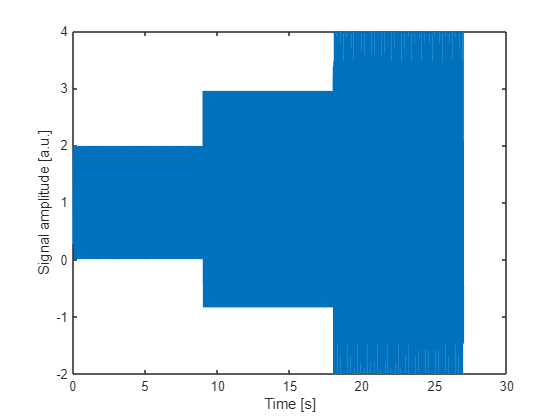



figure
plot(t,sns)
xlabel('Time [s]')
ylabel('Signal amplitude [a.u.]')

## Spectogram

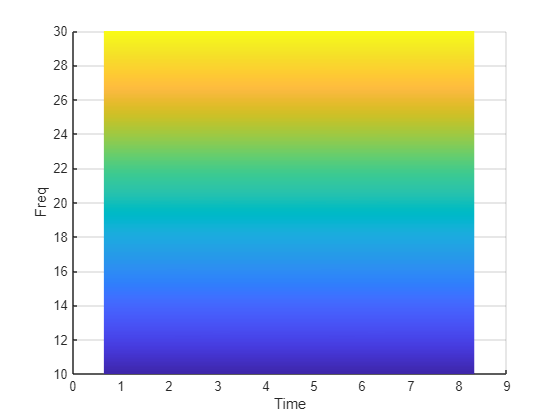

%%% time- freq repr based on STFT

[S, f, t] = spectrogram(s, WINDOW, NOVERLAP, f, fs);
[Snsn, f, tsns] = spectrogram(sns, WINDOW, NOVERLAP, f, fs);
figure
surf(t, f, abs(S));
shading interp;
xlabel('Time')
ylabel('Freq')
zlabel('Spectogram')

%
surf(tsns, f, abs(Snsn));
shading interp;
view(2)
xlabel('Time')
ylabel('Freq')
zlabel('Spectogram')

% NFFT can be changed, but window should be then changed aswell
% try to sadd upp some noise
